# Progetto: stabilizzazione, identificazione e controllo MPC di un pendolo inverso su carrello

#include

addpath('./functions');   %sottocartella con funzioni

### Obiettivi del controllo

`Gli obiettivi del controllo sono:`

`1.`` Il carrello può essere spostato in una nuova posizione compresa tra -10 e 10 con una variazione graduale del setpoint.`

`2.`` Quando si monitora tale variazione del setpoint, il tempo di salita dovrebbe essere inferiore a 4 secondi (per le prestazioni) e l'overshoot dovrebbe essere inferiore al 5% (per la robustezza).`

`3.`` Quando al pendolo viene applicata una perturbazione impulsiva di intensità 2, il carrello dovrebbe tornare alla sua posizione originale con uno spostamento massimo di 1. Il pendolo dovrebbe anche tornare alla posizione verticale con uno spostamento angolare di picco di 15 gradi (0,26 radianti).`

### Prima di cominciare

Nello script precedente [./stabilizzazione.mlx](matlab:open('./stabilizzazione.mlx')), si è trovata empiricamente la reazione di stato che stabilizzasse il sistema nel punto d'equilibrio.

Successivamente alla stabilizzazione empirica, il sistema è stato identificato nello script [./identificazione.mlx](matlab:open('./identificazione.mlx')) e adesso disponiamo di un modello lineare tempo discreto su cui progettare il controllo.

Eseguiamo le seguenti istruzioni per non perderci le dipendenze necessarie dal precedente script

%Variabili di sistema
M = 1; m = 1; g = 9.8; L = 0.5; Kd = 10;

%Condizione iniziale 
teta_zero = 0;

%Variabili di circuito e sensori
ritardo_misura = 1e-6;
limite_sup_att = 200;
limite_inf_att = -200;
tau_derivatore = 0.02;               
Gder = tf([1 0], [tau_derivatore 1]);
Ts_sens_x = 0.002;     
Ts_sens_teta = 0.002;
x_noise_power= 1.4576e-09;       
teta_noise_power =  1.6046e-11;   

%k stabilizzante
k1 = -20.3018;
k2 = -86.59;
k3 = 475.2216;
k4 = 409.0522;

%modelli identificati
folder_path = "id_models";
load(folder_path + '/sysid_u_x.mat');
load(folder_path + '/sysid_d_x.mat');
load(folder_path + '/sysid_u_teta.mat');
load(folder_path + '/sysid_d_teta.mat');

Il sistema identificato è:

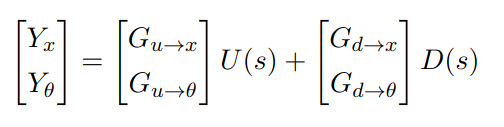

G_id = [G_u_x G_d_x; G_u_teta G_d_teta]

### MPC Control Toolbox

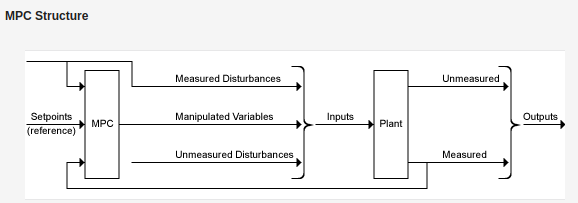

Grazie all'MPC Toolbox di Matlab, possiamo simulare degli **scenari di controllo** sulla base delle specifiche e fare un tuning manuale del nostro controllore MPC.

Settiamo l'I/O, indicando ingressi, disturbi, uscite.

- u, come ingresso manipolabile (MV)

- d, come disturbo noto (MD)

- x, teta come uscite misurabili (MO)

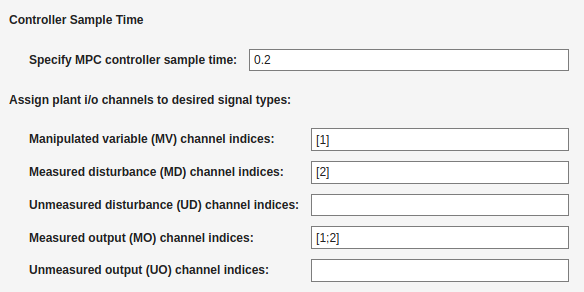

Adesso ricreiamo gli scenari di controllo su cui andremo ad effettuare il tuning del controllore:

`Scenario 1`

- riferimento di x: step di ampiezza 10

- riferimento di teta: 0 costante

- disturbo: nessuno (0 costante)

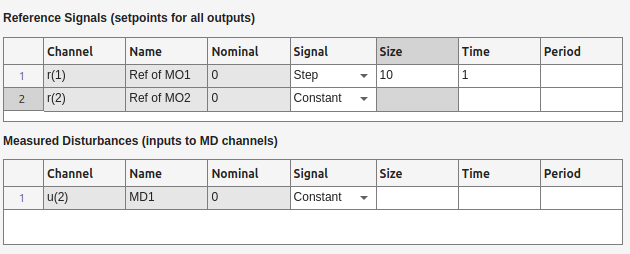

Desideriamo per tale scenario:

- x che va a regime con **tempo di assestamento di max 4 secondi**

- x che va a regime con **overshoot max del 5%**

- teta che **non superi in ampiezza 0.5 rad** (aggiunta da me, per restare nella zona di linearizzazione del pendolo e non avere problemi di stabilità)

`Scenario 2`

- riferimento di x: 0 costante

- riferimento di teta: 0 costante

- disturbo: impulso di ampiezza 2 (durata breve 0.33s ad 1 s)

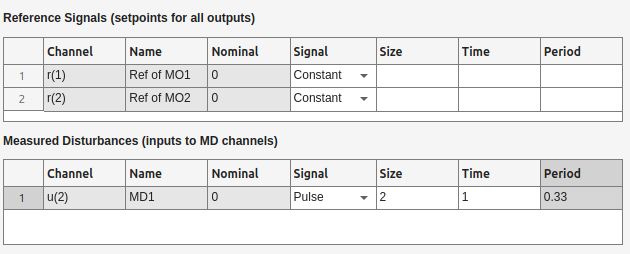

Desideriamo per tale scenario:

- x che torni a 0 e **non superi in ampiezza 1m**

- teta che **non superi in ampiezza 0.26 rad** 

A questo punto, sui due scenari si è visualizzato il comportamento del sistema a ciclo chiuso con controllo MPC.

Si è variato il livello di robustezza e performance di conseguenza finché non si è trovato un risultato soddisfacente.

Prediligendo un controllore robusto:

le richieste nei due scenari sono soddisfatte:

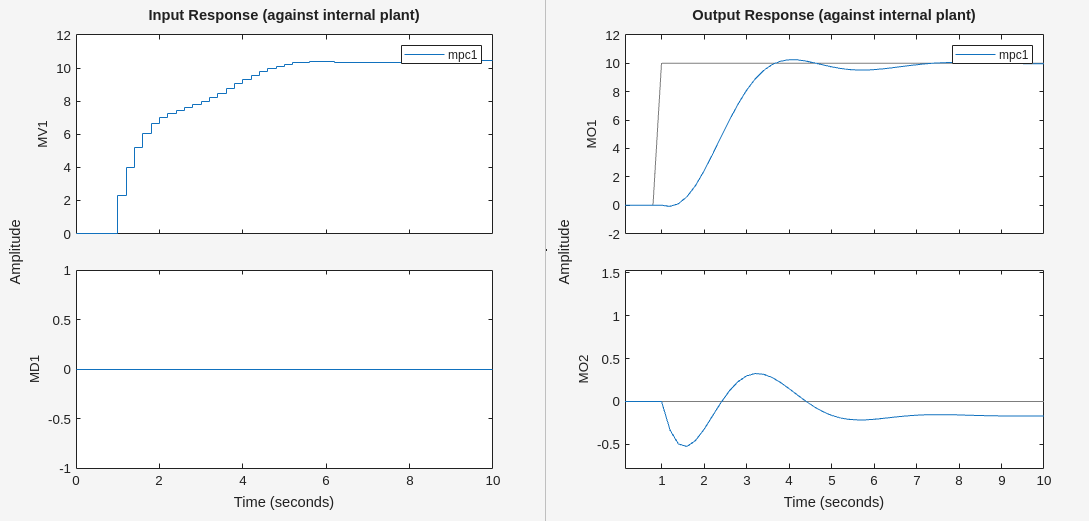

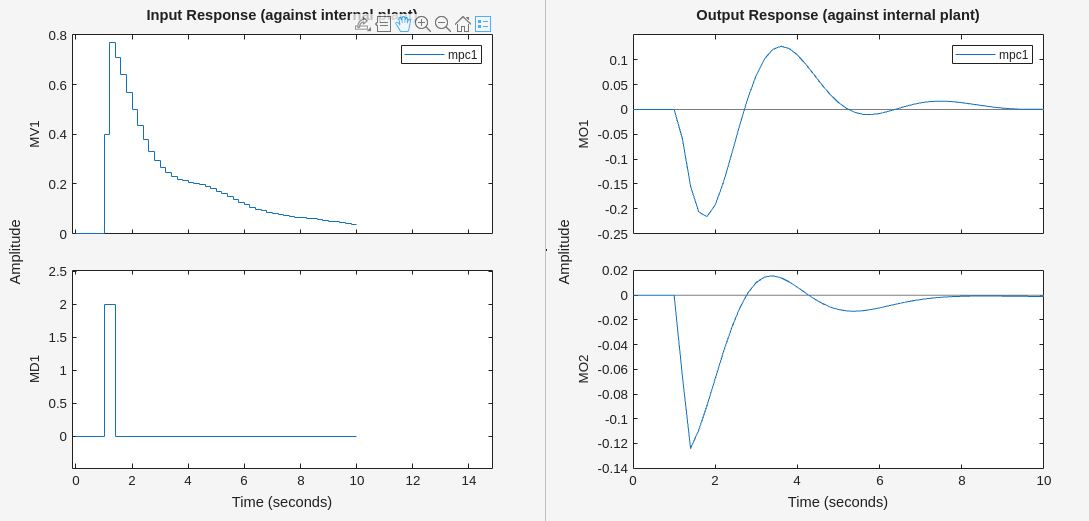

Il controllore MPC, che realizza questo comportamento a ciclo chiuso è stato estratto dal toolbox, portato nel workspace e salvato in un file. 

D'ora in poi verrà ripristinato ad ogni esecuzione:

load("controller_saving/mpc_save.mat"); %"mpc1"


G_id_extended =
 
  From input 1 to output...
       -0.03856 z^-1 + 0.1575 z^-2 + 0.03513 z^-3 - 0.04848 z^-4
   1:  ---------------------------------------------------------
              1 - 1.159 z^-1 - 0.2665 z^-2 + 0.5353 z^-3
 
       -0.147 z^-1 + 0.3008 z^-2 - 0.1548 z^-3
   2:  ---------------------------------------
            1 - 1.784 z^-1 + 0.8469 z^-2
 
  From input 2 to output...
       -0.02147 z^-1 - 0.004983 z^-2 + 0.01783 z^-3
   1:  --------------------------------------------
        1 - 2.721 z^-1 + 2.518 z^-2 - 0.7935 z^-3
 
       -0.003181 z^-1 - 0.004335 z^-2
   2:  ------------------------------
        1 - 1.773 z^-1 + 0.8377 z^-2
 
Sample time: 0.2 seconds
Discrete-time transfer function.


### Test di controllo

Adesso non ci resta che testare il nostro controllo in Simulink.

[./simulink_models/test_MPC.slx](matlab:open('./simulink_models/test_MPC.slx'))

Il controllo tirato fuori dal blocco MPC viene calcolato sul sistema identificato e dato in ingresso anche al sistema vero. Faremo un confronto dei due comportamenti.

- 1° test: Ingresso a gradino, senza disturbo:

% setto l'input
set_input_simulink_tmpc(1, 10, 0, 0); %solo gradino amp=10 a stp_time = 1

% eseguo la simulazione
simOut = sim('./simulink_models/test_MPC', 10); %10 secondi

% plot risposta
plot_id_and_real_x_teta(simOut);

- 2° test: Posizione di quiete con disturbo impulsivo:

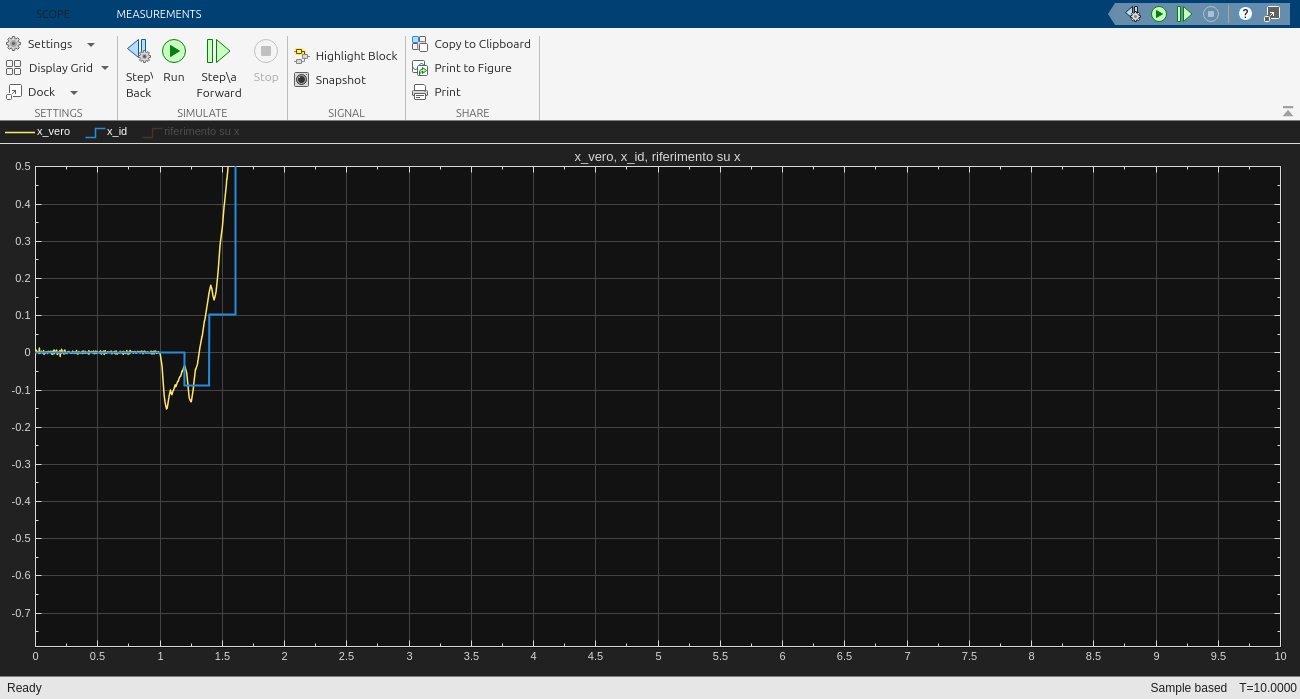

% setto l'input
set_input_simulink_tmpc(0, 0, 0.33, 2); 

% eseguo la simulazione
simOut = sim('./simulink_models/test_MPC', 10); %10 secondi

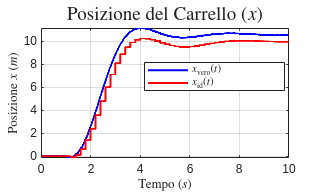

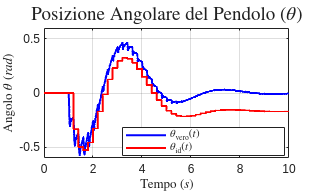

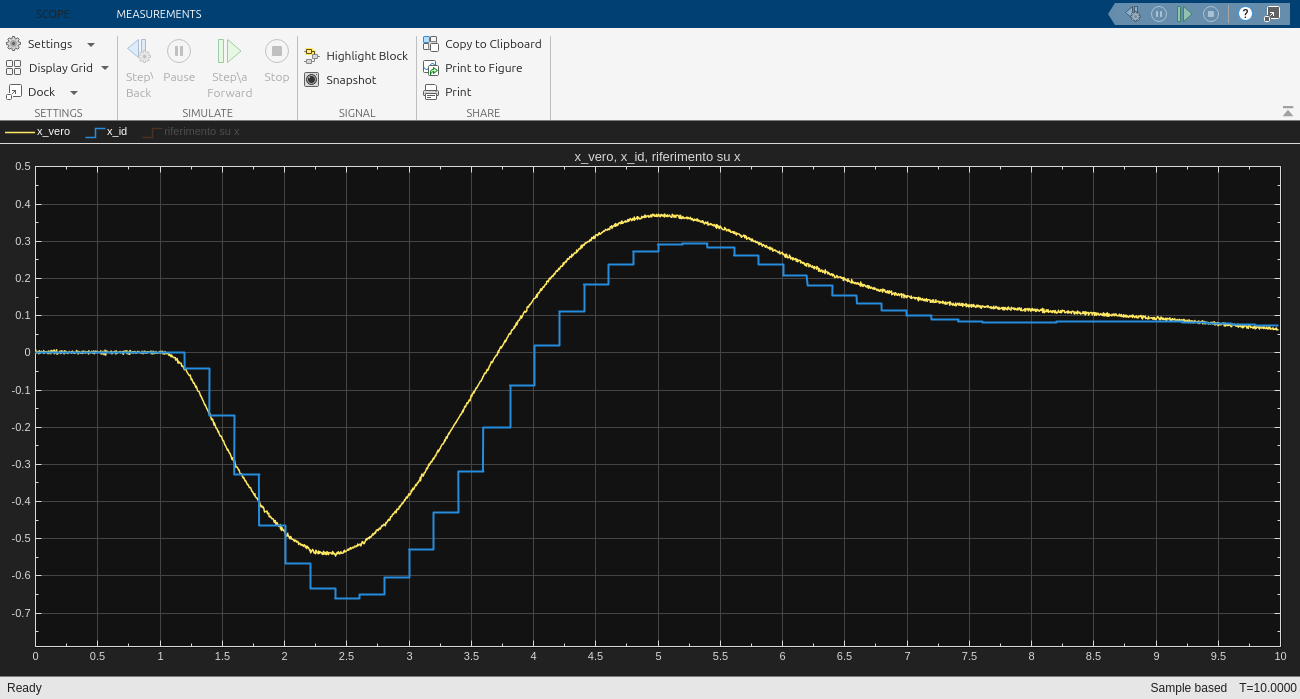

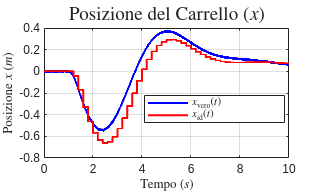

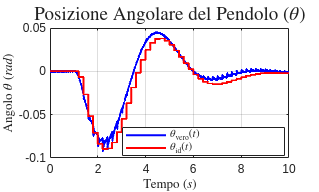


% plot risposta
plot_id_and_real_x_teta(simOut);

Come vediamo, il comportamento di x e teta reali è più che soddisfacente e rispetta le specifiche perfettamente.

Al massimo si segnala un piccolo errore a regime (PROVA FEEDFORWARD)!!!!!!!!!

### Conclusioni parte 3

Il controllore è stato progettato (o meglio l'MPC è stato tarato coi parametri giusti) in modo che soddisfi i requisiti della traccia.

Il progetto si può dire concluso con successo.